% Load temperature data from txt.
TEMP = [];
DATA = [];
folder = "E:/MatlabWorkStation/Point1";
files = dir(folder);
files = files(~[files.isdir]);

for i = 1:length(files)
    filename = fullfile(folder, files(i).name);
    DATA = load(filename);
    %判断数据长度
    if length(DATA) > length(TEMP)
        TEMP = padarray(TEMP,length(DATA) - length(TEMP),nan,'post');
        TEMP = [TEMP, DATA(:,1)];
    elseif length(DATA) == length(TEMP)
        TEMP = [TEMP, DATA(:,1)];
    elseif length(DATA) < length(TEMP)
        DATA = padarray(DATA,length(TEMP) - length(DATA),nan,'post');
        TEMP = [TEMP, DATA(:,1)];
    end
end
close all;

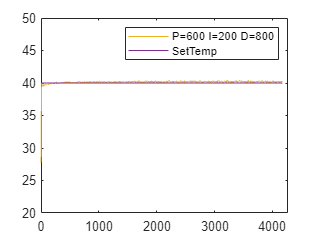

% Draw the line chart by looping.

figure(1);
legend('');     % Display the legend.
X = linspace(1,length(TEMP),length(TEMP));
for i = 1:length(files)
    str = strsplit(files(i).name,'_');
    plot(X,TEMP(:,i),'DisplayName',sprintf("P=%s I=%s D=%s",str{2},str{3},str{4}));
    %legend(sprintf("%s",files(i).name));
    hold on
end
SETTEMP = DATA(:,2);
plot(X,SETTEMP,'DisplayName','SetTemp');
%legend("SetTemp");
xlim([0 (length(SETTEMP)+100)]);
ylim([20 50]);

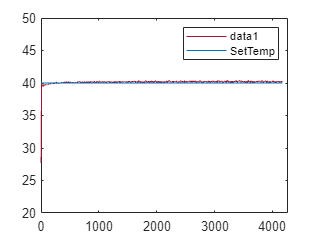

% Demo
figure(2);
legend('');
legend("show");
plot(X,TEMP(:,1));
hold on
plot(X,SETTEMP,'DisplayName','SetTemp');
xlim([0 (length(SETTEMP)+100)]);
ylim([20 50]);